close all;clear all;clc;

# AMPLITUDE MODULATION AND DEMODULATION

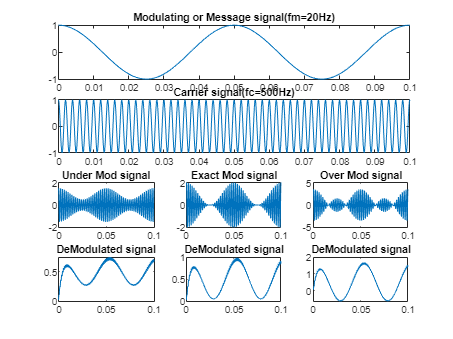

fs=8000; %SAMPLE FREQUENCY
fm=20; %THREE MESSAGE SIGNAL FREQUENCY
fc=500; %CARRIER FREQUENCY
Am=1; %MESSAGE AMPLITUDE
Ac=1; %CARRIER AMPLITUDE

t=[0:0.1*fs]/fs; %TIME DURATION

m=Am*cos(2*pi*fm*t); 
c=Ac*cos(2*pi*fc*t);
ka=0.5;
u=ka*Am;

s1=Ac*(1+u*cos(2*pi*fm*t)).*cos(2*pi*fc*t);



subplot(4,3,1:3);
plot(t,m);
title('Modulating or Message signal(fm=20Hz)');

subplot(4,3,4:6);
plot(t,c);
title('Carrier signal(fc=500Hz)');


subplot(4,3,7);
plot(t,s1);
title('Under Mod signal');

Am=2;
ka=0.5;
u=ka*Am;
s2=Ac*(1+u*cos(2*pi*fm*t)).*cos(2*pi*fc*t);

subplot(4,3,8);
plot(t,s2);
title('Exact Mod signal');

Am=5;
ka=0.5;
u=ka*Am;
s3=Ac*(1+u*cos(2*pi*fm*t)).*cos(2*pi*fc*t);
subplot(4,3,9);
plot(t,s3);
title('Over Mod signal');

r1=s1.*c;
[b a]=butter(1,0.01); %BUTTERWORTH FILTER
mr1=filter(b,a,r1); %DEPTH OF MODULATION
subplot(4,3,10);
plot(t,mr1);
title('DeModulated signal');
r2=s2.*c;
[b a]=butter(1,0.01);
mr2=filter(b,a,r2);
subplot(4,3,11);
plot(t,mr2);
title('DeModulated signal');
r3=s3.*c;
[b a]=butter(1,0.01);
mr3=filter(b,a,r3);
subplot(4,3,12);
plot(t,mr3);
title('DeModulated signal');